**Gato lazo abierto**

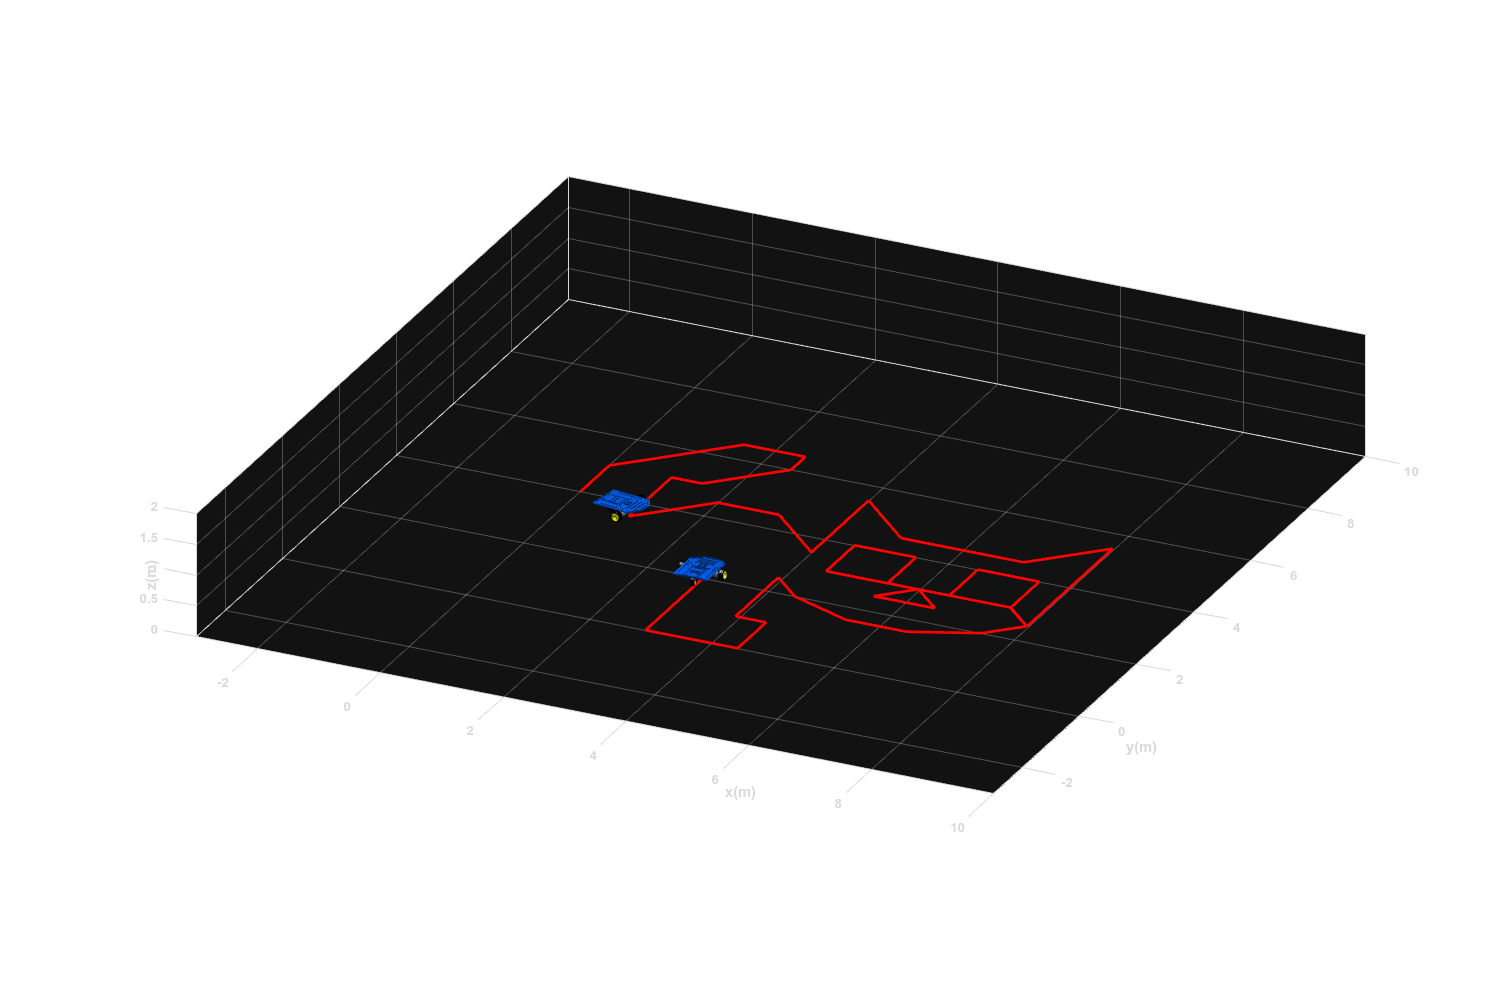

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tf = 92.99;             % Tiempo de simulacion en segundos (s)
ts = 0.1;            % Tiempo de muestreo en segundos (s)
t = 0: ts: tf;       % Vector de tiempo
N = length(t);       % Muestras

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = 0;    % Posicion inicial eje x
y1(1) = 4;   % Posicion inicial eje y
phi(1) = pi/2;   % Orientacion inicial del robot

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1, N+1);  % Posicion en el punto de control (eje x) en metros (m)
hy = zeros(1, N+1);  % Posicion en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posicion en el punto de control del robot en el eje x
hy(1) = y1(1); % Posicion en el punto de control del robot en el eje y


%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

u = [1*ones(1,10) 0*ones(1,10)    2.12*ones(1,10) 0*ones(1,10)    1*ones(1,10) 0*ones(1,10)    0.5*ones(1,10) 0*ones(1,10)    1.4*ones(1,10) 0*ones(1,10)       0.5*ones(1,10) 0*ones(1,10)      1.5*ones(1,10) 0*ones(1,10)     1.4*ones(1,10)   0*ones(1,10)   1*ones(1,10)    0*ones(1,10)   1.4*ones(1,10)     0*ones(1,10)       2*ones(1,10)        0*ones(1,10)  1.4*ones(1,10)   0*ones(1,10)      2*ones(1,10)     0*ones(1,10)   1.4*ones(1,10)          0*ones(1,10)    3*ones(1,10)         0*ones(1,10)  0.7*ones(1,10)        0*ones(1,10)   1*ones(1,10)   0*ones(1,10)      1*ones(1,10)     0*ones(1,10)    1*ones(1,10)       0*ones(1,10)      0.5*ones(1,10)        0*ones(1,10)    0.7*ones(1,10)            0*ones(1,10)           1*ones(1,10)              0*ones(1,10)  0.7*ones(1,10)          0*ones(1,10)   0.5*ones(1,10)       0*ones(1,10)   1*ones(1,10)      0*ones(1,10)    1*ones(1,10)     0*ones(1,10)   1*ones(1,10)    0*ones(1,10)      3*ones(1,10)       0*ones(1,10)   0.7*ones(1,10)  0*ones(1,10)      0.7*ones(1,10)    0*ones(1,10)      1.11*ones(1,10)   0*ones(1,10)      1*ones(1,10)      0*ones(1,10)       1.11*ones(1,10)    0*ones(1,10)      0.7*ones(1,10)     0*ones(1,10)       1.5*ones(1,10)   0*ones(1,10)    0.5*ones(1,10)   0*ones(1,10)       1*ones(1,10)    0*ones(1,10)      1.5*ones(1,10)    0*ones(1,10)       2*ones(1,10)      0*ones(1,10)      1*ones(1,10)   0*ones(1,10)       0.7*ones(1,10)     0*ones(1,10)       0.5*ones(1,10)    0*ones(1,10)      1*ones(1,10)      0*ones(1,10)     1*ones(1,10)       0*ones(1,10)        2*ones(1,10)    0*ones(1,10)            3.04*ones(1,10)   0*ones(1,10)          1*ones(1,10)]; % Velocidad lineal de referencia (m/s)
w = [0*ones(1,10) -pi/4*ones(1,10) 0*ones(1,10) -pi/4*ones(1,10) 0*ones(1,10) -pi/2*ones(1,10) 0*ones(1,10) -pi/4*ones(1,10) 0*ones(1,10)    -pi/4*ones(1,10)   0*ones(1,10)   pi/2*ones(1,10)   0*ones(1,10)   3*pi/4*ones(1,10) 0*ones(1,10)   -pi/4*ones(1,10)  0*ones(1,10)   -pi/4*ones(1,10)   0*ones(1,10)   3*pi/4*ones(1,10) 0*ones(1,10)   -3*pi/4*ones(1,10)   0*ones(1,10)   pi/4*ones(1,10)   0*ones(1,10)  pi/4*ones(1,10)     0*ones(1,10)    -3*pi/4*ones(1,10)    0*ones(1,10)   -3*pi/4*ones(1,10)    0*ones(1,10)    -pi/4*ones(1,10)   0*ones(1,10)   pi/2*ones(1,10)   0*ones(1,10)   pi/2*ones(1,10)   0*ones(1,10)   -pi/2*ones(1,10)        0*ones(1,10)   3*pi/4*ones(1,10)      0*ones(1,10)      -3*pi/4*ones(1,10)           0*ones(1,10)        -3*pi/4*ones(1,10)    0*ones(1,10)    3*pi/4*ones(1,10)     0*ones(1,10)    -pi/2*ones(1,10)   0*ones(1,10)   pi/2*ones(1,10)    0*ones(1,10)  pi/2*ones(1,10)   0*ones(1,10)    pi/2*ones(1,10)   0*ones(1,10)   -pi/4*ones(1,10)   0*ones(1,10)    -pi/2*ones(1,10)  0*ones(1,10)      -pi/8*ones(1,10)  0*ones(1,10)     -pi/8*ones(1,10)   0*ones(1,10)      -pi/8*ones(1,10)   0*ones(1,10)       -pi/8*ones(1,10)    0*ones(1,10)     3*pi/4*ones(1,10)    0*ones(1,10)   pi/2*ones(1,10)   0*ones(1,10)   -pi/2*ones(1,10)   0*ones(1,10)    -pi/2*ones(1,10)  0*ones(1,10)      -pi/2*ones(1,10)   0*ones(1,10)      pi/2*ones(1,10)   0*ones(1,10)   pi/4*ones(1,10)    0*ones(1,10)       pi/4*ones(1,10)    0*ones(1,10)      pi/2*ones(1,10)   0*ones(1,10)     -pi/2*ones(1,10)   0*ones(1,10)      -pi/2*ones(1,10)    0*ones(1,10)    -161*pi/360*ones(1,10)   0*ones(1,10)     -19*pi/360*ones(1,10)  0*ones(1,10)]; % Velocidad angular de referencia (rad/s)



for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    %Aplicamos el modelo cinemático diferencial para obtener las
    %velocidades en x, y, phi
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));
    phip= w(k);

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([25 25]); % Orientacion de la figura
axis([-3 10 -3 10 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

**Gato lazo cerrado**

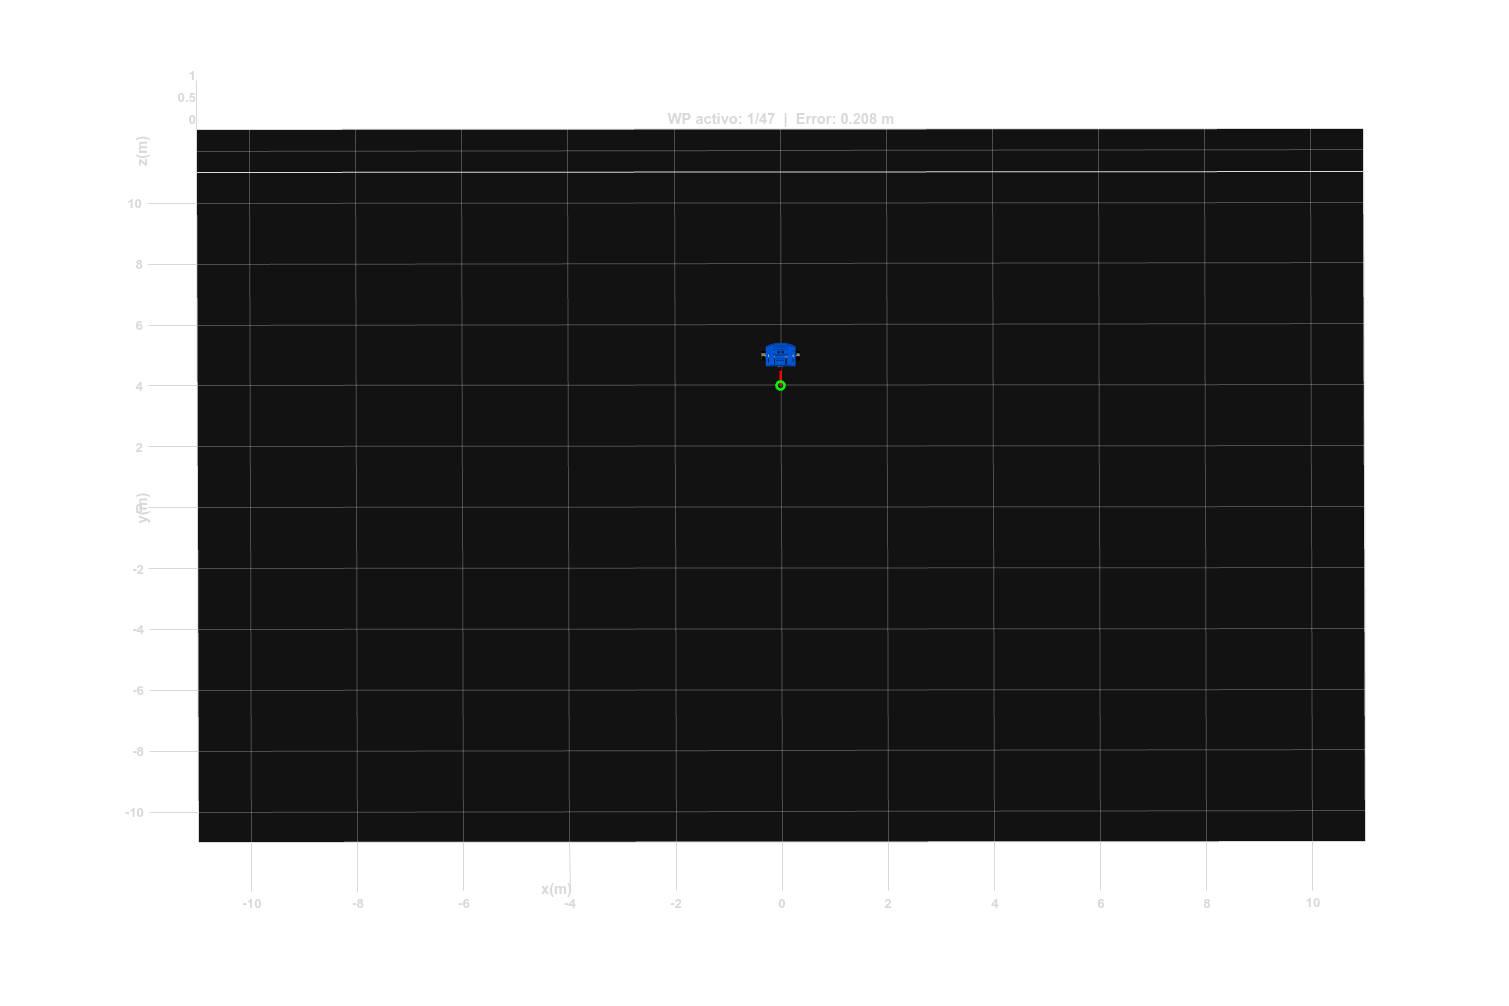

%Limpieza de pantalla
clc


%% 1. TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf = 92.99;
ts = 0.05;
t  = 0:ts:tf;
N  = length(t);

%% 2. WAYPOINTS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Cada fila: [xd, yd, tolerancia]
% Las ganancias se calculan solas igual que antes, aquí solo defines destinos
waypoints = [
     0,    5.0,  0.12;
     1.5,  6.5,  0.12;
     2.5,  6.5,  0.12;
     2.5,  6.0,  0.12;
     1.5,  5.0,  0.12;
     1.0,  5.0,  0.12;
     1.0,  3.5,  0.12;
     2.0,  4.5,  0.12;
     3.0,  4.5,  0.12;
     4.0,  3.5,  0.12;
     4.0,  5.5,  0.12;
     5.0,  4.5,  0.12;
     7.0,  4.5,  0.12;
     8.0,  5.5,  0.12;
     8.0,  2.5,  0.12;
     7.5,  3.0,  0.12;
     7.5,  4.0,  0.12;
     6.5,  4.0,  0.12;
     6.5,  3.0,  0.12;
     6.0,  3.0,  0.12;
     6.5,  2.5,  0.12;
     5.5,  2.5,  0.12;
     6.0,  3.0,  0.12;
     5.5,  3.0,  0.12;
     5.5,  4.0,  0.12;
     4.5,  4.0,  0.12;
     4.5,  3.0,  0.12;
     7.5,  3.0,  0.12;
     8.0,  2.5,  0.12;
     7.5,  2.0,  0.12;
     6.5,  1.5,  0.12;
     5.5,  1.5,  0.12;
     4.5,  2.0,  0.12;
     4.0,  2.5,  0.12;
     4.0,  1.0,  0.12;
     4.5,  1.0,  0.12;
     4.5,  0.0,  0.12;
     3.0,  0.0,  0.12;
     3.0,  2.0,  0.12;
     2.0,  2.0,  0.12;
     1.5,  1.5,  0.12;
     1.5,  1.0,  0.12;
     2.5,  1.0,  0.12;
     2.5,  0.0,  0.12;
     0.5,  0.0,  0.12;
     0.0,  3.0,  0.12;
     0.0,  4.0,  0.12;% regreso al origen
];
numWP  = size(waypoints, 1);
wpIdx  = 1;

%% 3. CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
x1(1)   = 0;
y1(1)   = 4;
phi(1)  = pi/2;
hx(1)   = x1(1);
hy(1)   = y1(1);

%% 4. PARÁMETROS CONTROL ADAPTATIVO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% (exactamente igual que tu código original, sin cambios)
Kv0     = 0.8;
Kw0     = 1.5;
alpha_v = 0.08;
alpha_w = 0.05;

Kv_max  = 2.5;   Kw_max = 3.5;
Kv_min  = 0.3;   Kw_min = 0.5;

v_max   = 1.2;
w_max   = 1.5;

v_prev  = 0;
w_prev  = 0;
beta    = 0.85;

%% 5. BUCLE DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for k = 1:N

    % --- Waypoint activo ---
    hxd = waypoints(wpIdx, 1);
    hyd = waypoints(wpIdx, 2);
    tol = waypoints(wpIdx, 3);

    %% a) ERRORES
    hxe(k) = hxd - hx(k);
    hye(k) = hyd - hy(k);

    Error(k) = sqrt(hxe(k)^2 + hye(k)^2);

    phi_d  = atan2(hye(k), hxe(k));
    e_phi  = phi_d - phi(k);
    e_phi  = atan2(sin(e_phi), cos(e_phi));   % normalización angular

    %% b) GANANCIAS AUTO-SINTONIZABLES (sin cambios)
    Kv(k) = Kv0 + alpha_v * Error(k);
    Kw(k) = Kw0 + alpha_w * abs(e_phi);

    Kv(k) = min(max(Kv(k), Kv_min), Kv_max);
    Kw(k) = min(max(Kw(k), Kw_min), Kw_max);

    %% c) CONTROLADOR (sin cambios)
    v_raw = Kv(k) * Error(k);
    v_raw = v_raw * cos(e_phi);       % reduce v si hay mucho error angular
    w_raw = Kw(k) * e_phi;

    %% d) SATURACIÓN DE VELOCIDADES (sin cambios)
    v_raw = max(min(v_raw,  v_max), -v_max);
    w_raw = max(min(w_raw,  w_max), -w_max);

    %% e) FILTRO SUAVIZANTE (sin cambios)
    v(k) = beta * v_prev + (1 - beta) * v_raw;
    w(k) = beta * w_prev + (1 - beta) * w_raw;
    v_prev = v(k);
    w_prev = w(k);

    %% f) CAMBIO DE WAYPOINT
    wpLog(k) = wpIdx;
    if Error(k) <= tol && wpIdx < numWP
        wpIdx = wpIdx + 1;
        % Reset del filtro para arranque limpio hacia el nuevo punto
        v_prev = 0;
        w_prev = 0;
    end

    %% g) MODELO CINEMÁTICO (sin cambios)
    phi(k+1)  = phi(k)  + w(k) * ts;
    xp1       = v(k) * cos(phi(k));
    yp1       = v(k) * sin(phi(k));
    x1(k+1)   = x1(k)  + xp1 * ts;
    y1(k+1)   = y1(k)  + yp1 * ts;
    hx(k+1)   = x1(k+1);
    hy(k+1)   = y1(k+1);
end

%% 6. SIMULACIÓN 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
scene = figure;
set(scene, 'Color', 'white');
set(gca,   'FontWeight', 'bold');
sizeScreen = get(0, 'ScreenSize');
set(scene, 'position', sizeScreen);
camlight('headlight');
axis equal; grid on; box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([-0.1 35]);
axis([-11 11 -11 11 0 1]);

scale = 4;
MobileRobot_5;
hold on;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale);

% Dibujar todos los waypoints numerados

H2 = plot3(hx(1), hy(1), 0, 'r', 'LineWidth', 2);
     plot3(hx(1), hy(1), 0, 'go', 'LineWidth', 2);   % posición inicial


%% Animación
for k = 1:N
    delete(H1); delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'LineWidth', 2);
    title(sprintf('WP activo: %d/%d  |  Error: %.3f m', wpLog(k), numWP, Error(k)));
    pause(ts);
end

%% 7. GRÁFICAS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph = figure;
set(graph, 'position', sizeScreen);

subplot(4,1,1)
plot(t, v, 'b', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'); ylabel('[m/s]'); legend('Velocidad lineal');

subplot(4,1,2)
plot(t, w, 'g', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'); ylabel('[rad/s]'); legend('Velocidad angular');

subplot(4,1,3)
plot(t, Error, 'r', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'); ylabel('[m]'); legend('Error de posición');

subplot(4,1,4)
stairs(t, wpLog, 'k', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'); ylabel('Índice'); legend('Waypoint activo');
yticks(1:numWP);
ylim([0.5, numWP + 0.5]);

**Mariposa lazo abierto**

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tf = 56.99;             % Tiempo de simulacion en segundos (s)
ts = 0.1;            % Tiempo de muestreo en segundos (s)
t = 0: ts: tf;       % Vector de tiempo
N = length(t);       % Muestras

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = 0;    % Posicion inicial eje x
y1(1) = 1;   % Posicion inicial eje y
phi(1) = pi/2;   % Orientacion inicial del robot

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1, N+1);  % Posicion en el punto de control (eje x) en metros (m)
hy = zeros(1, N+1);  % Posicion en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posicion en el punto de control del robot en el eje x
hy(1) = y1(1); % Posicion en el punto de control del robot en el eje y


%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

u = [0.5*ones(1,10)   0*ones(1,10)           1.11*ones(1,10)    0*ones(1,10)           0.7*ones(1,10)       0*ones(1,10)               1.11*ones(1,10)      0*ones(1,10)              1.11*ones(1,10)      0*ones(1,10)                1*ones(1,10)     0*ones(1,10)                  1.11*ones(1,10)      0*ones(1,10)               1.41*ones(1,10)     0*ones(1,10)     0.7*ones(1,10)     0*ones(1,10)       0.7*ones(1,10)      0*ones(1,10)    1.4*ones(1,10)  0*ones(1,10)            1.11*ones(1,10)     0*ones(1,10)             1*ones(1,10)       0*ones(1,10)              1.11*ones(1,10)       0*ones(1,10)              1.11*ones(1,10)       0*ones(1,10)                 0.707106*ones(1,10)    0*ones(1,10)                1.11*ones(1,10)     0*ones(1,10)              0.5*ones(1,10)    0*ones(1,10)                  1.11*ones(1,10)         0*ones(1,10)                    0.7*ones(1,10)     0*ones(1,10)               1.11*ones(1,10)      0*ones(1,10)              2.15*ones(1,10)     0*ones(1,10)     2.15*ones(1,10)      0*ones(1,10)      0.7*ones(1,10)    0*ones(1,10)       0.7*ones(1,10)          0*ones(1,10)        2.15*ones(1,10)    0*ones(1,10)     2.15*ones(1,10)      0*ones(1,10)                 2.22*ones(1,10)     0*ones(1,10)              0.7*ones(1,10)];
w = [0*ones(1,10)     -127*pi/360*ones(1,10)   0*ones(1,10)       217*pi/360*ones(1,10)  0*ones(1,10)         -23*pi/225*ones(1,10)    0*ones(1,10)         -133*pi/450*ones(1,10)    0*ones(1,10)         -317*pi/900*ones(1,10)       0*ones(1,10)     -133*pi/900*ones(1,10)       0*ones(1,10)         71.56*pi/180*ones(1,10)    0*ones(1,10)        pi*ones(1,10)    0*ones(1,10)       -pi/2*ones(1,10)   0*ones(1,10)        pi*ones(1,10)   0*ones(1,10)    71.96*pi/180*ones(1,10)   0*ones(1,10)       -26.56*pi/180*ones(1,10)   0*ones(1,10)    -317*pi/900*ones(1,10)    0*ones(1,10)          -133*pi/400*ones(1,10)    0*ones(1,10)          -23*pi/225*ones(1,10)        0*ones(1,10)      126.8*pi/180*ones(1,10)       0*ones(1,10)        -75*pi/180*ones(1,10)      0*ones(1,10)        -63.43*pi/180*ones(1,10)      0*ones(1,10)            -71.6*pi/180*ones(1,10)         0*ones(1,10)       18.4*pi/180*ones(1,10)     0*ones(1,10)         -63.4*pi/180*ones(1,10)   0*ones(1,10)      pi*ones(1,10)     0*ones(1,10)        -pi/4*ones(1,10)   0*ones(1,10)    -pi/2*ones(1,10)    0*ones(1,10)            -pi/4*ones(1,10)    0*ones(1,10)     pi*ones(1,10)      0*ones(1,10)       -63.43*pi/180*ones(1,10)     0*ones(1,10)       -71.57*pi/180*ones(1,10)    0*ones(1,10)];



for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    %Aplicamos el modelo cinemático diferencial para obtener las
    %velocidades en x, y, phi
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));
    phip= w(k);

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([25 25]); % Orientacion de la figura
axis([-3 10 -3 10 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

**Mariposa lazo cerrado**

%Limpieza de pantalla
clc

%% 1. TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf = 93.99;
ts = 0.05;
t  = 0:ts:tf;
N  = length(t);

%% 2. WAYPOINTS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Cada fila: [xd, yd, tolerancia]
% Las ganancias se calculan solas igual que antes, aquí solo defines destinos
waypoints = [
     0.0,    1.5,  0.12;
     1.0,    2.0,  0.12;
     0.5,    2.5,  0.12;
     0.0,    3.5,  0.12;
     0.5,    4.5,  0.12;
     1.5,    4.5,  0.12;
     2.5,    4.0,  0.12;
     0.5,    4.5,  0.12;
     3.5,    5.0,  0.12;
     0.5,    4.5,  0.12;
     3.0,    4.5,  0.12;
     2.5,    5.0,  0.12;
     3.0,    4.5,  0.12;
     3.5,    4.0,  0.12;
     4.5,    4.5,  0.12;
     5.5,    4.5,  0.12;
     6.0,    3.5,  0.12;
     5.5,    2.5,  0.12;
     5.0,    2.0,  0.12;
     6.0,    1.5,  0.12;
     6.0,    1.0,  0.12;
     5.0,    0.5,  0.12;
     4.5,    1.0,  0.12;
     3.5,    1.5,  0.12;
     3.5,    4.0,  0.12;
     3.5,    1.5,  0.12;
     3.0,    1.0,  0.12;
     2.5,    1.5,  0.12;
     2.5,    4.0,  0.12;
     2.5,    1.5,  0.12;
     0.5,    0.5,  0.12;
     0.0,    1.0,  0.12;
     
    
];
numWP  = size(waypoints, 1);
wpIdx  = 1;

%% 3. CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
x1(1)   = 0;
y1(1)   = 1;
phi(1)  = pi/2;
hx(1)   = x1(1);
hy(1)   = y1(1);

%% 4. PARÁMETROS CONTROL ADAPTATIVO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% (exactamente igual que tu código original, sin cambios)
Kv0     = 0.8;
Kw0     = 1.5;
alpha_v = 0.08;
alpha_w = 0.05;

Kv_max  = 2.5;   Kw_max = 3.5;
Kv_min  = 0.3;   Kw_min = 0.5;

v_max   = 1.2;
w_max   = 1.5;

v_prev  = 0;
w_prev  = 0;
beta    = 0.85;

%% 5. BUCLE DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for k = 1:N

    % --- Waypoint activo ---
    hxd = waypoints(wpIdx, 1);
    hyd = waypoints(wpIdx, 2);
    tol = waypoints(wpIdx, 3);

    %% a) ERRORES
    hxe(k) = hxd - hx(k);
    hye(k) = hyd - hy(k);

    Error(k) = sqrt(hxe(k)^2 + hye(k)^2);

    phi_d  = atan2(hye(k), hxe(k));
    e_phi  = phi_d - phi(k);
    e_phi  = atan2(sin(e_phi), cos(e_phi));   % normalización angular

    %% b) GANANCIAS AUTO-SINTONIZABLES (sin cambios)
    Kv(k) = Kv0 + alpha_v * Error(k);
    Kw(k) = Kw0 + alpha_w * abs(e_phi);

    Kv(k) = min(max(Kv(k), Kv_min), Kv_max);
    Kw(k) = min(max(Kw(k), Kw_min), Kw_max);

    %% c) CONTROLADOR (sin cambios)
    v_raw = Kv(k) * Error(k);
    v_raw = v_raw * cos(e_phi);       % reduce v si hay mucho error angular
    w_raw = Kw(k) * e_phi;

    %% d) SATURACIÓN DE VELOCIDADES (sin cambios)
    v_raw = max(min(v_raw,  v_max), -v_max);
    w_raw = max(min(w_raw,  w_max), -w_max);

    %% e) FILTRO SUAVIZANTE (sin cambios)
    v(k) = beta * v_prev + (1 - beta) * v_raw;
    w(k) = beta * w_prev + (1 - beta) * w_raw;
    v_prev = v(k);
    w_prev = w(k);

    %% f) CAMBIO DE WAYPOINT
    wpLog(k) = wpIdx;
    if Error(k) <= tol && wpIdx < numWP
        wpIdx = wpIdx + 1;
        % Reset del filtro para arranque limpio hacia el nuevo punto
        v_prev = 0;
        w_prev = 0;
    end

    %% g) MODELO CINEMÁTICO (sin cambios)
    phi(k+1)  = phi(k)  + w(k) * ts;
    xp1       = v(k) * cos(phi(k));
    yp1       = v(k) * sin(phi(k));
    x1(k+1)   = x1(k)  + xp1 * ts;
    y1(k+1)   = y1(k)  + yp1 * ts;
    hx(k+1)   = x1(k+1);
    hy(k+1)   = y1(k+1);
end

%% 6. SIMULACIÓN 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
scene = figure;
set(scene, 'Color', 'white');
set(gca,   'FontWeight', 'bold');
sizeScreen = get(0, 'ScreenSize');
set(scene, 'position', sizeScreen);
camlight('headlight');
axis equal; grid on; box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([-0.1 35]);
axis([-11 11 -11 11 0 1]);

scale = 4;
MobileRobot_5;
hold on;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale);

% Dibujar todos los waypoints numerados

H2 = plot3(hx(1), hy(1), 0, 'r', 'LineWidth', 2);
     plot3(hx(1), hy(1), 0, 'go', 'LineWidth', 2);   % posición inicial

%% Animación
for k = 1:N
    delete(H1); delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'LineWidth', 2);
    title(sprintf('WP activo: %d/%d  |  Error: %.3f m', wpLog(k), numWP, Error(k)));
    pause(ts);
end

%% 7. GRÁFICAS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph = figure;
set(graph, 'position', sizeScreen);

subplot(4,1,1)
plot(t, v, 'b', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'); ylabel('[m/s]'); legend('Velocidad lineal');

subplot(4,1,2)
plot(t, w, 'g', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'); ylabel('[rad/s]'); legend('Velocidad angular');

subplot(4,1,3)
plot(t, Error, 'r', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'); ylabel('[m]'); legend('Error de posición');

subplot(4,1,4)
stairs(t, wpLog, 'k', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'); ylabel('Índice'); legend('Waypoint activo');
yticks(1:numWP);
ylim([0.5, numWP + 0.5]);

**Conclusiones**

El control en lazo abierto es más simple, no requiere sensores ni sintonización y reproduce la figura exactamente en simulación, pero acumula errores y se distorsiona ante deslizamiento, mala calibración o perturbaciones, por lo que figuras cerradas no terminan donde empezaron. El control en lazo cerrado corrige esas desviaciones mediante realimentación (encoders, IMU, visión), logrando trayectorias robustas y repetibles en hardware real, a costa de mayor complejidad, más sensores, carga computacional y riesgo de inestabilidad si está mal sintonizado o si la odometría tiene drift como en nuestro caso.